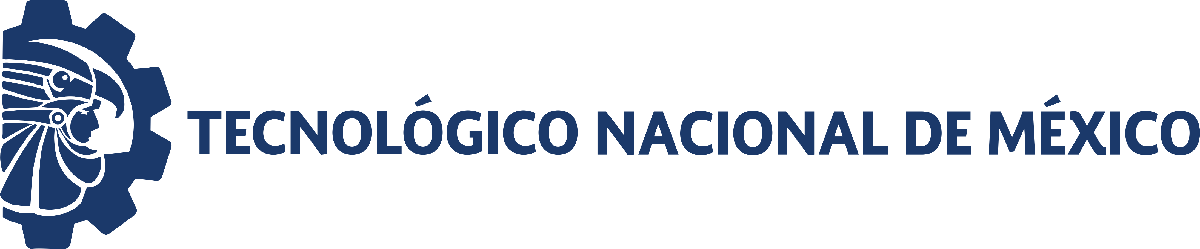                                 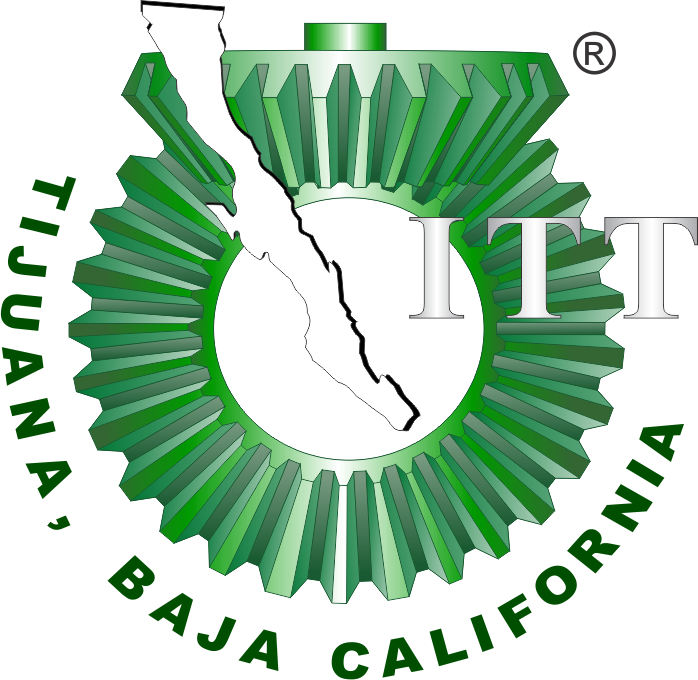

# Práctica 5:  Analisis de sistemas biologicos

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

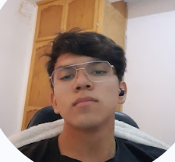

Nombre del alumno: **Chaparro Zamora Alain Yahir**

Número de control: **21212147**

Correo institucional: **l21212147@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Simulation**

### **Chaotic attractor**


clc; clear; close all; warning('off','all')
r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.555; y0 = 0.148; z0 = 0.172;
tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,1,rhoi,dt,tend);
plotEDOs(t,x,y,z);
exportgraphics(gcf,'Chaotic attractor.pdf','ContentType','vector');


### Periodic orbit

r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.254781; y0 = 0.115167; z0 = 0.600527;
tend = 1000;

[t,x,y,z] = system(x0,y0,z0,P,0.9,rhoi,dt,tend);
plotEDOs(t,x,y,z);
exportgraphics(gcf,'Periodic orbit.pdf','ContentType','vector');

### intern limit cycle

r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.2; y0 = 0.6; z0 = 0.1;
tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,0.8,rhoi,dt,tend);
plotEDOs(t,x,y,z);
exportgraphics(gcf,'intern limit cycle.pdf','ContentType','vector');


### extern limit cycle

r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.4; y0 = 0.2; z0 = 0.4;
tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,0.75,rhoi,dt,tend);
plotEDOs(t,x,y,z);
exportgraphics(gcf,'extern limit cycle.pdf','ContentType','vector');


### Convergence towards an equilibrium point

r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.5; y0 = 0.5; z0 = 0.4;
tend = 1000;
[t,x,y,z] = system2(x0,y0,z0,P,0.5,rhoi,dt,tend);
plotEDOs(t,x,y,z);
exportgraphics(gcf,'Convergence towards an equilibrium point.pdf','ContentType','vector');

### Convergence towards an equilibrium point (NoNormalized)

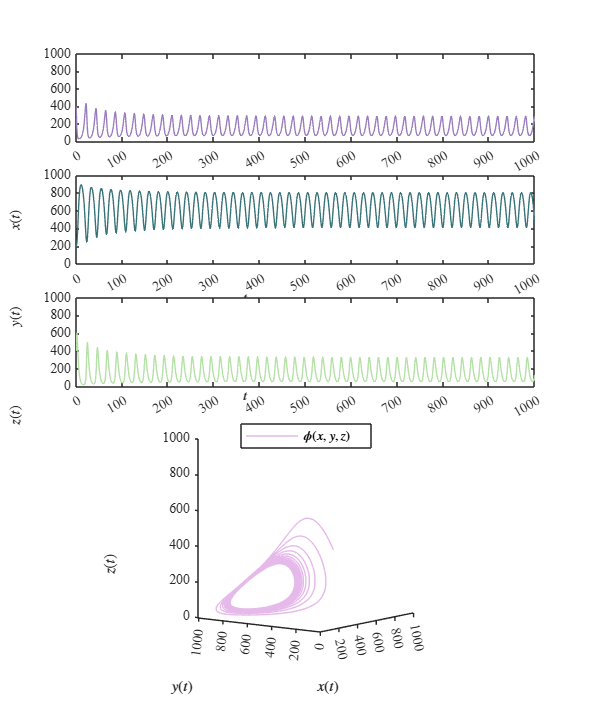

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.75/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.4*xmax; y0 = 0.2*ymax; z0 = 0.4*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z);
exportgraphics(gcf,'External Limit Cycle [No normalized].png','ContentType','vector')

De los cinco límites (comportamientos dinámicos) descritos en el documento, el que representa mejor el modelo biológico desde una perspectiva fisiológica sería el caso 5:

***Convergencia hacia un punto de equilibrio***

Este comportamiento es el más representativo del modelo por varias razones:

- **Estabilidad fisiológica**: En sistemas biológicos reales, la tendencia natural suele ser hacia un equilibrio homeostático. La convergencia a un punto de equilibrio refleja una situación donde las poblaciones celulares alcanzan un estado estable, lo que es coherente con muchos procesos biológicos controlados.

- **Relevancia clínica**: Desde una perspectiva médica, un estado de equilibrio donde coexisten células patológicas, células sanas y células efectoras representa una condición controlada de la enfermedad, similar a una enfermedad crónica estable o una remisión parcial.

- **Efectividad intermedia del sistema inmune**: Con a₁₂ = 0.5, la fracción de células patológicas eliminadas por células sanas está en un valor intermedio, lo que representa un sistema inmune funcionando con moderada efectividad - ni demasiado débil (que causaría crecimiento descontrolado) ni demasiado fuerte (que eliminaría completamente las células patológicas).

- **Predictibilidad**: A diferencia del comportamiento caótico o las oscilaciones cíclicas, la convergencia a un punto de equilibrio permite predecir el estado futuro del sistema, lo que es fundamental para la planificación de tratamientos.

Los otros comportamientos (atractor caótico, órbita periódica, y ciclos límite) representan situaciones más inestables o atípicas que, aunque posibles en ciertos contextos patológicos (como fluctuaciones en condiciones autoinmunes o recaídas periódicas), son generalmente menos representativas de un funcionamiento biológico sostenible a largo plazo.

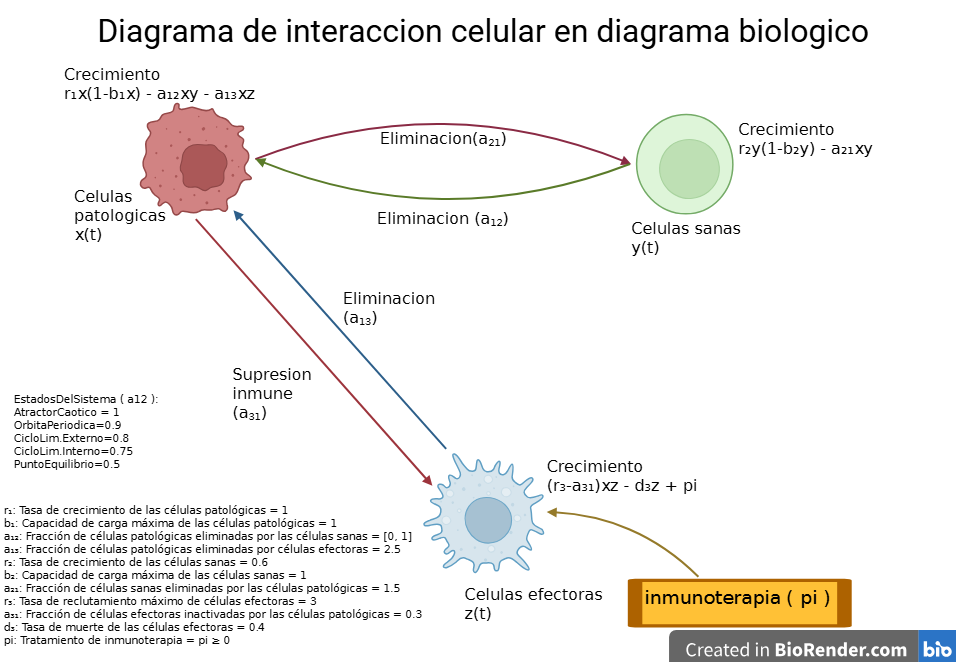

## Equilibrium points and jacobian matrix

clear
syms x y z r1 b1 a12 a13 r2 b2 a21 r3 a31 d3 rho1

dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rho1;
J = jacobian([dx,dy,dz],[x,y,z]); disp(J)

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z == 0;
dy = r2*y*(1 - b2*y) - a21*x*y == 0;
dz = (r3 - a31)*x*z - d3*z + rho1 == 0;
equilibria = solve([dx,dy,dz],[x,y,z]);

for i = 1:6
  xe(i,1) = simplify(equilibria.x(i));
  ye(i,1) = simplify(equilibria.y(i));
  ze(i,1) = simplify(equilibria.z(i));

    disp(['Equilibrium points of the system: ', num2str(i)])
    disp(['x', num2str(i), ' = ', char(xe(i,1))]);
    disp(['y', num2str(i), ' = ', char(ye(i,1))]);
    disp(['z', num2str(i), ' = ', char(ze(i,1))]);
end

Equilibrium points of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1 = 0


z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4 = 0


y4 = 1/b2


z4 = rho1/d3


Equilibrium points of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5 = 0


z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6 = 0


y6 = 0


z6 = rho1/d3


## Equilibrium points without treatment ( chaotic attractor )

clear
a12l = [1; 0.9; 0.8; 0.75; 0.5];

r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 1; b2 = 4; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rho1 = 0;

for i = 1:numel(a12l)
    a12 = a12l(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

    x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 1


Treatment rho1 = 0


       x          y           z              Lambda1               Lambda2          Lambda3 
    _______    _______    __________    __________________    __________________    ________

    0.14815          0       0.34074    0.0059259+0.56303i    0.0059259-0.56303i     0.77778
    0.14815    0.19444       0.26296     0.028842+0.48323i     0.028842-0.48323i    -0.82361
        1.2       -0.2    2.4672e-17           -1+0i                0.6+0i             1.296
          0       0.25             0           -1+0i               0.75+0i                 0
          1          0    2.4672e-17           -1+0i               1.08+0i              -0.5
          0          0             0            0+0i                  1+0i                 1



Equilibrium points with a12 = 0.9


Treatment rho1 = 0


       x          y             z              Lambda1               Lambda2          Lambda3 
    _______    ________    ___________    __________________    __________________    ________

    0.14815           0        0.34074    0.0059259+0.56303i    0.0059259-0.56303i     0.77778
    0.14815     0.19444        0.27074     0.026453+0.49148i     0.026453-0.49148i    -0.81883
     1.1698    -0.18868    -4.1119e-17           -1+0i            0.58491+0i            1.2634
          0        0.25              0           -1+0i              0.775+0i                 0
          1           0     2.4672e-17           -1+0i               1.08+0i              -0.5
          0           0              0            0+0i                  1+0i                 1



Equilibrium points with a12 = 0.8


Treatment rho1 = 0


       x          y             z              Lambda1               Lambda2          Lambda3 
    _______    ________    ___________    __________________    __________________    ________

    0.14815           0        0.34074    0.0059259+0.56303i    0.0059259-0.56303i     0.77778
    0.14815     0.19444        0.27852     0.024084+0.49966i     0.024084-0.49966i    -0.81409
     1.1429    -0.17857    -8.2239e-18           -1+0i            0.57143+0i            1.2343
          0        0.25              0           -1+0i                0.8+0i                 0
          1           0     2.4672e-17           -1+0i               1.08+0i              -0.5
          0           0              0            0+0i                  1+0i                 1



Equilibrium points with a12 = 0.75


Treatment rho1 = 0


       x          y             z              Lambda1               Lambda2          Lambda3 
    _______    ________    ___________    __________________    __________________    ________

    0.14815           0        0.34074    0.0059259+0.56303i    0.0059259-0.56303i     0.77778
    0.14815     0.19444        0.28241     0.022907+0.50373i     0.022907-0.50373i    -0.81174
     1.1304    -0.17391    -4.1119e-17           -1+0i            0.56522+0i            1.2209
          0        0.25              0           -1+0i             0.8125+0i                 0
          1           0     2.4672e-17           -1+0i               1.08+0i              -0.5
          0           0              0            0+0i                  1+0i                 1



Equilibrium points with a12 = 0.5


Treatment rho1 = 0


       x          y            z              Lambda1               Lambda2          Lambda3 
    _______    ________    __________    __________________    __________________    ________

    0.14815           0       0.34074    0.0059259+0.56303i    0.0059259-0.56303i     0.77778
    0.14815     0.19444       0.30185     0.017104+0.52384i     0.017104-0.52384i    -0.80013
     1.0769    -0.15385    2.4672e-17           -1+0i            0.53846+0i            1.1631
          0        0.25             0           -1+0i              0.875+0i                 0
          1           0    2.4672e-17           -1+0i               1.08+0i              -0.5
          0           0             0            0+0i                  1+0i                 1



## Equilibrium points with treatment ( chaotic attractor )

clear
a12l = [1; 0.9; 0.8; 0.75; 0.5];

r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 1; b2 = 4; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rho1 = 1.1*(d3*r1)/a13;

for i = 1:numel(a12l)
    a12 = a12l(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

    x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 1


Treatment rho1 = 0.176


        x           y            z        Lambda1    Lambda2     Lambda3 
    _________    ________    _________    _______    ________    ________

    -0.012761           0       0.4051    0.18676    -0.18778      1.0191
     -0.05896     0.27211      0.31474    0.34712    -0.37595     -1.0643
       1.4071    -0.27767    -0.051777    -1.3399     0.92517       1.638
            0        0.25         0.44          0          -1       -0.35
       1.1609           0    -0.064364    -1.3543      1.4472    -0.74136
            0           0         0.44          0        -0.1           1



Equilibrium points with a12 = 0.9


Treatment rho1 = 0.176


        x           y            z        Lambda1    Lambda2     Lambda3 
    _________    ________    _________    _______    ________    ________

    -0.012761           0       0.4051    0.18676    -0.18778      1.0191
    -0.053011     0.26988      0.32405    0.33498    -0.35858     -1.0602
        1.371    -0.26411    -0.053307    -1.3419     0.89978      1.6083
            0        0.25         0.44          0          -1      -0.325
       1.1609           0    -0.064364    -1.3543      1.4472    -0.74136
            0           0         0.44          0        -0.1           1



Equilibrium points with a12 = 0.8


Treatment rho1 = 0.176


        x           y            z        Lambda1    Lambda2     Lambda3 
    _________    ________    _________    _______    ________    ________

    -0.012761           0       0.4051    0.18676    -0.18778      1.0191
    -0.047437     0.26779      0.33328    0.32224    -0.34132     -1.0559
       1.3384    -0.25192    -0.054764    -1.3438     0.87648       1.582
            0        0.25         0.44          0          -1        -0.3
       1.1609           0    -0.064364    -1.3543      1.4472    -0.74136
            0           0         0.44          0        -0.1           1



Equilibrium points with a12 = 0.75


Treatment rho1 = 0.176


        x           y            z        Lambda1    Lambda2     Lambda3 
    _________    ________    _________    _______    ________    ________

    -0.012761           0       0.4051    0.18676    -0.18778      1.0191
    -0.044779     0.26679      0.33787    0.31563     -0.3327     -1.0537
       1.3234    -0.24626    -0.055467    -1.3446     0.86554        1.57
            0        0.25         0.44          0          -1     -0.2875
       1.1609           0    -0.064364    -1.3543      1.4472    -0.74136
            0           0         0.44          0        -0.1           1



Equilibrium points with a12 = 0.5


Treatment rho1 = 0.176


        x           y            z        Lambda1    Lambda2     Lambda3 
    _________    ________    _________    _______    ________    ________

    -0.012761           0       0.4051    0.18676    -0.18778      1.0191
     -0.03262     0.26223       0.3606    0.27981    -0.28886     -1.0425
       1.2577    -0.22163     -0.05875    -1.3484     0.81674      1.5188
            0        0.25         0.44          0          -1      -0.225
       1.1609           0    -0.064364    -1.3543      1.4472    -0.74136
            0           0         0.44          0        -0.1           1



### Convergence towards an equilibrium (normalized) equilibrium points with treatment

clear
r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
a12 = 0.5;

rho1 = 1.1*(d3*r1)/a13;

for i = 1:numel(a12)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

   x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 0.5


Treatment rho1 = 0.176


        x          y           z        Lambda1          Lambda2              Lambda3     
    _________    ______    _________    ________    _________________    _________________

    -0.012761         0       0.4051     0.18676    -0.18778+0i           0.61914+0i      
     -0.21756    1.5439      0.17824     0.42689    -0.68532+0.26573i    -0.68532-0.26573i
      -1.6343    5.0857     0.036571    -0.46672     -1.3577+0.48356i     -1.3577-0.48356i
            0         1         0.44           0        -0.6+0i              -0.6+0i      
       1.1609         0    -0.064364     -1.3543      1.4472+0i           -1.1414+0i      
            0         0         0.44           0        -0.1+0i               0.6+0i      



### Convergence towards an equilibrium (no normalized) equilibrium points without treatment

clear
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.75/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 0;

for i = 1:numel(a12)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

  x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 0.00075


Treatment rho1 = 0


       x         y            z              Lambda1               Lambda2               Lambda3     
    _______    ______    ___________    __________________    __________________    _________________

     148.15         0         340.74    0.0059259+0.56303i    0.0059259-0.56303i     0.37778+0i      
     148.15    629.63         151.85      -0.5485+0i           0.091286+0.33248i    0.091286-0.33248i
    -285.71    1714.3    -1.2418e-13     -0.37143+0.34523i     -0.37143-0.34523i    -0.30857+0i      
          0      1000              0         -0.6+0i               0.25+0i                 0+0i      
       1000         0     1.2047e-14           -1+0i               1.08+0i              -0.9+0i      
          0         0              0            0+0i                0.6+0i       

### Convergence towards an equilibrium (no normalized) equilibrium points with treatment

clear
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.75/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 1.1*(d3*r1)/a13;

for i = 1:numel(a12)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

      xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

  x = [x1; x2; x3; x4; x5; x6];
y = [y1; y2; y3; y4; y5; y6];
z = [z1; z2; z3; z4; z5; z6];

fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rho1 = ', num2str(rho1), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)

end

Equilibrium points with a12 = 0.00075


Treatment rho1 = 176


           x                y                 z                Lambda1              Lambda2             Lambda3     
    _______________    ____________    _______________    _________________    _________________    ________________

    -12.761+0i            0+0i           405.1+0i         0.18676+0i           -0.18778+0i          0.61914+0i      
    -68.783+373.07i    1172-932.69i     75.926+130.58i    -1.0393-0.097459i     0.63898+0.10021i    -0.3084+0.58671i
    -68.783-373.07i    1172+932.69i     75.926-130.58i    -1.0393+0.097459i     0.63898-0.10021i    -0.3084-0.58671i
          0+0i         1000+0i             440+0i               0+0i               -0.6+0i            -0.85+0i      
     1160.9+0i            0+0i         -64.364+0i         -1.3543+0i             1.4472+0i   

### Convergence towards an equilibrium (no normalized) point with treatment

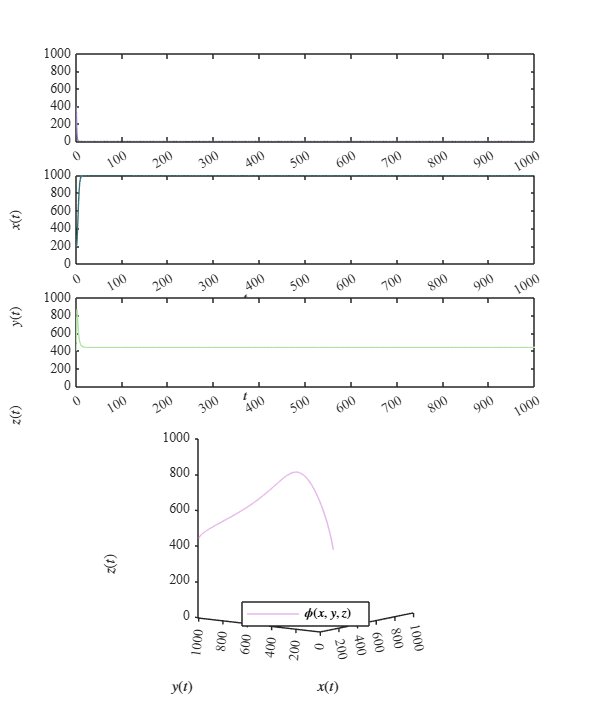

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0./ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 1.1*(d3*r1)/a13;
x0 = 0.4*xmax; y0 = 0.2*ymax; z0 = 0.4*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z);
exportgraphics(gcf,'Convergence towards an equilibrium (normalized) point with treatment .png','ContentType','vector')

## Funciones

### Sistema

function [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend)
r1 = P(1); b1 = P(2); a13 = P(3);
r2 = P(4); b2 = P(5); a21 = P(6);
r3 = P(7); a31 = P(8); d3 = P(9);
t = (0:dt:tend)';
n = round(tend/dt);
x = zeros(n+1,1); x(1) = x0;
y = zeros(n+1,1); y(1) = y0;
z = zeros(n+1,1); z(1) = z0;
for i = 1:n
[fx,fy,fz] = f(x(i),y(i),z(i));
xn = x(i) + fx*dt;
yn = y(i) + fy*dt;
zn = z(i) + fz*dt;
[fxn,fyn,fzn] = f(xn,yn,zn);
x(i+1) = x(i) + (fx + fxn)*dt/2;
y(i+1) = y(i) + (fy + fyn)*dt/2;
z(i+1) = z(i) + (fz + fzn)*dt/2;
end
function [dx,dy,dz] = f(x,y,z)
dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rhoi;
end
end

function [t, x, y, z] = system2(x0, y0, z0, P, a12, rhoi, dt, tend)
 r1 = P(1); b1 = P(2); a13 = P(3);
 r2 = P(4); b2 = P(5); a21 = P(6);
 r3 = P(7); a31 = P(8); d3 = P(9);
 t = (0:dt:tend)';
 n = round(tend/dt);
 x = zeros(n+1, 1); x(1) = x0;
 y = zeros(n+1, 1); y(1) = y0;
 z = zeros(n+1, 1); z(1) = z0;
 for i = 1:n
 [fx, fy, fz] = f(x(i), y(i), z(i));
 xn = x(i) + fx * dt;
16
 yn = y(i) + fy * dt;
 zn = z(i) + fz * dt;
 [fxn, fyn, fzn] = f(xn, yn, zn);
 x(i+1) = x(i) + (fx + fxn) * dt / 2;
 y(i+1) = y(i) + (fy + fyn) * dt / 2;
 z(i+1) = z(i) + (fz + fzn) * dt / 2;
 end
 function [dx, dy, dz] = f(x, y, z)
 dx = r1 * x * (1 - b1 * x) - a12 * x * y - a13 * x * z;
 dy = r2 * y * (1 - b2 * y) - a21 * x * y;
 dz = (r3 - a31) * x * z - d3 * z + rhoi;
 end
end


Soluciones

function plotEDOs(t,x,y,z)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,15,18])
morado = [0.50, 0.00, 0.75]; 
negro = [0.00, 0.00, 0.00];  
azul = [0.04, 0.10, 1.00];

subplot(5, 4, 1:4);
set(gca,'FontName','Times New Roman'); fontsize(10,'points');
hold on; box on; grid off;
plot(t,x,'-','LineWidth',1,'Color', azul)
xlabel('$t$','Interpreter','Latex')
ylabel('$x(t)$','Interpreter','Latex')
xlim([0 1000]); xticks(0:100:1000)
ylim([0 1]); yticks(0:0.2:1)
subplot(5, 4, 5:8);
set(gca,'FontName','Times New Roman'); fontsize(10,'points');
hold on; box on; grid off;
plot(t,y,'-','LineWidth',1, 'Color',negro)
xlabel('$t$','Interpreter','Latex')
ylabel('$y(t)$','Interpreter','Latex')
xlim([0 1000]); xticks(0:100:1000)
ylim([0 1]); yticks(0:0.2:1)
subplot(5, 4, 9:12);
set(gca,'FontName','Times New Roman'); fontsize(10,'points');
hold on; box on; grid off;
plot(t,z,'-','LineWidth',1,'Color', morado)
xlabel('$t$','Interpreter','Latex')
ylabel('$z(t)$','Interpreter','Latex')
xlim([0 1000]); xticks(0:100:1000)
ylim([0 1]); yticks(0:0.2:1)
subplot(5, 4, [14, 15, 18, 19]);
set(gca,'FontName','Times New Roman'); fontsize(10,'points');
hold on; box off; grid off;
plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', morado)
set(gca, 'XDir', 'reverse');
set(gca, 'YDir', 'reverse');
xlabel('$x(t)$', 'Interpreter', 'Latex');
ylabel('$y(t)$', 'Interpreter', 'Latex');
zlabel('$z(t)$', 'Interpreter', 'Latex');
view(127.5, 7.5);
xlim([0 1]); ylim([0 1]); zlim([0 1]);
xticks(0.2:0.2:1); yticks(0:0.2:1); zticks(0:0.2:1);
L = legend('$\phi(x,y,z)$');
set(L,'Interpreter','Latex','Location','NorthEast','Box','On')
end

function plotEDOs2(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])
    colores = [155, 125, 190;
                55, 115, 120;
                180, 225, 165;
                230, 185, 235;
                ]/255;
    % colororder(colores)
    
    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', colores(1,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
   xlim([0 1000]); xticks(0:100:1000)
 ylim([0 1E3]); yticks(0:0.2E3:1E3)
    
    subplot(5, 4, 5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', colores(2,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
  xlim([0 1000]); xticks(0:100:1000)
 ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', colores(3,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
 xlim([0 1000]); xticks(0:100:1000)
 ylim([0 1E3]); yticks(0:0.2E3:1E3)


    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', colores(4,:))
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    view(127.5, 7.5);
xlim([0 1E3]); ylim([0 1E3]); zlim([0 1E3]);
 xticks(0.2E3:0.2E3:1E3); yticks(0:0.2E3:1E3); zticks(0:0.2E3:1E3);
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')
end
